# 各种语句

- if语句

- for语句

- while语句

- switch-case语句

- try-catch语句

matlab和其他语言不一样，他不是通过花括号{}或者缩进来写代码块，而是通过**end代表结束**

## if语句

else和elseif都不是必须的，如果有else，else必须放在最后。

A = [];
if isempty(A)
    disp('变量为空');
end
% 学分
score = 70;
if score>=85
    disp('你的成绩为A');
elseif score>=75
    disp('你的成绩为B');
elseif score>=65
    disp('你的成绩为C');
elseif score>=60
    disp('你的成绩为D');
else
    disp('你的成绩为F');
end

## **for语句**

for i = [1,2,3,4,5,6]
    i
end
for i = {1,2,3}
    i
end
% 最常用的方法
for i = 1:5
    i
end

## while语句

i = 1;
while i<5
    i
    i = i+1;
end

无限循环可以用while实现

while true

    代码

    退出条件

end

i = 1;
while true
    i
    i = i+1;
    % 当i大于5时跳出循环
    if i>5
        break;
    end
end

## continue和break在循环语句的使用

continue表示跳出一次循环，break表示跳出整个循环

continue和break一定要放在for或者while语句中。

for i = 1:5
    % 当i等于3时，仅跳过本次循环
    if i == 3
        continue;
    end
    i
end
for i = 1:5
    % 当i等于3时，跳出整个循环
    if i == 3
        break;
    end
    i
end

双层循环中break和continue

for i = 1:3
    for j = 1:3
        if j == 2
            break;
        end
        fprintf('(i,j)=(%d,%d)\r\n',i,j);
    end
end
for i = 1:3
    for j = 1:3
        if j == 2
            continue;
        end
        fprintf('(i,j)=(%d,%d)\r\n',i,j);
    end
end

## **switch-case语句**

`switch`` 数字或者字符串`

`   case 数字或者字符串`

`      代码`

`   case 数字或者字符串`

`      代码`

`    ...`

`   otherwise`

`      代码`

`end`

a = 'cat'
switch a
    case 'cat'
        disp('喵喵');
    case 1
        disp('110');
    case 'dog'
        disp('旺旺');
    otherwise
        disp('没有符合的选项');
end

## **try-catch语句**

`try`

`   一段可能会出错的代码`

`catch ``exception[可以不填写]`

`   出错后怎么处理`

`end`

try
    % 尝试打开不存在的函数
    sing('国歌')
catch
    % 处理
    disp('不存在sing函数')
end

# **函数**

    当你使用matlab写程序时，新建一个m文件，然后开始敲代码，敲着敲着发现越写越多，逻辑越来越混乱，虽然可以通过注释的方法增加可阅性，但是看到很长一段代码，心里还是会很不舒服的，这时就需要封装代码了！函数是matlab最主要的封装方式。

## **格式**

示例

将其保存为m文件，注意**文件名不能为中文**，且**文件名要和函数名一样**

% 运行函数
disp_score(86);
disp_score(50);

可以看到当你将代码封装函数之后，直接调用函数就能出结果。

封装代码可以**隐藏实现的细节**，让用户直接调用即可。

## **函数的输入输出**

- 输入

function myfun(x1,...,xM)

这样子是写死的，就是必须传入M个参数。那有没有什么办法可以想传几个就几个呢？答案是肯定的。

使用varargin作为输入参数

myfun1('小米',1,2,{5,5})

从示例中可以看出varargin是一个元胞数组。

- 输出

% 接受四个输出
[y1,y2,y3,y4] = myfun2
% 只接受第一个输出
[y1] = myfun2
% 接受第1和第4个输出
[y1,~,~,y4] = myfun2
% 不接受任何输出
myfun2

使用varargout可以和varargin一样，不指定输出多少个。

[a] = myfun3
[a,b] = myfun3
[a,~,c] = myfun3

## **return在函数中的使用**

return类似于循环语句的break，不过break是跳出循环体，而return是跳出函数体。

c = my_add(13,44)
c = my_add([13,44],[3,5])

## **匿名函数**

匿名函数顾名思义就是没有函数名的函数。

格式：**函数句柄** = @(输入参数)(**一条语句**);

现在我要实现一个求$y=x^2 +2x+1$的函数

y = f1(10)
% 匿名函数实现
f2 = @(x)(x^2+2*x+1);
y = f2(10)

匿名函数里只能写一条语句，计算的结果就是返回值。

# **matlab自带函数**

matlab封装了很多很多函数，我们要学会去使用它。

matlab有十分丰富的说明文档，我们要学会查看文档。

在matlab界面的右上角有个输入框，比如我现在不知道dir这个函数是什么，我们就可以在这里输入dir，然后按回车键。

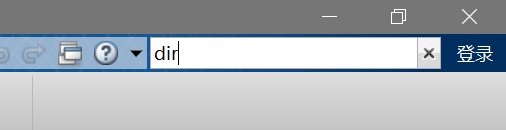

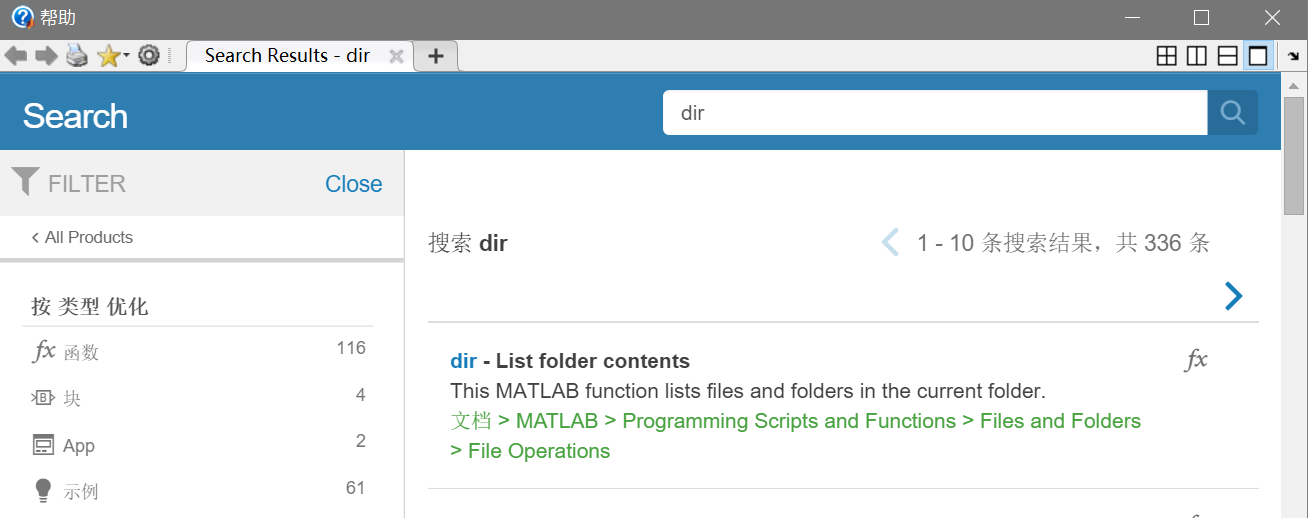

点击进去，可以看到里面有非常详细的解释。

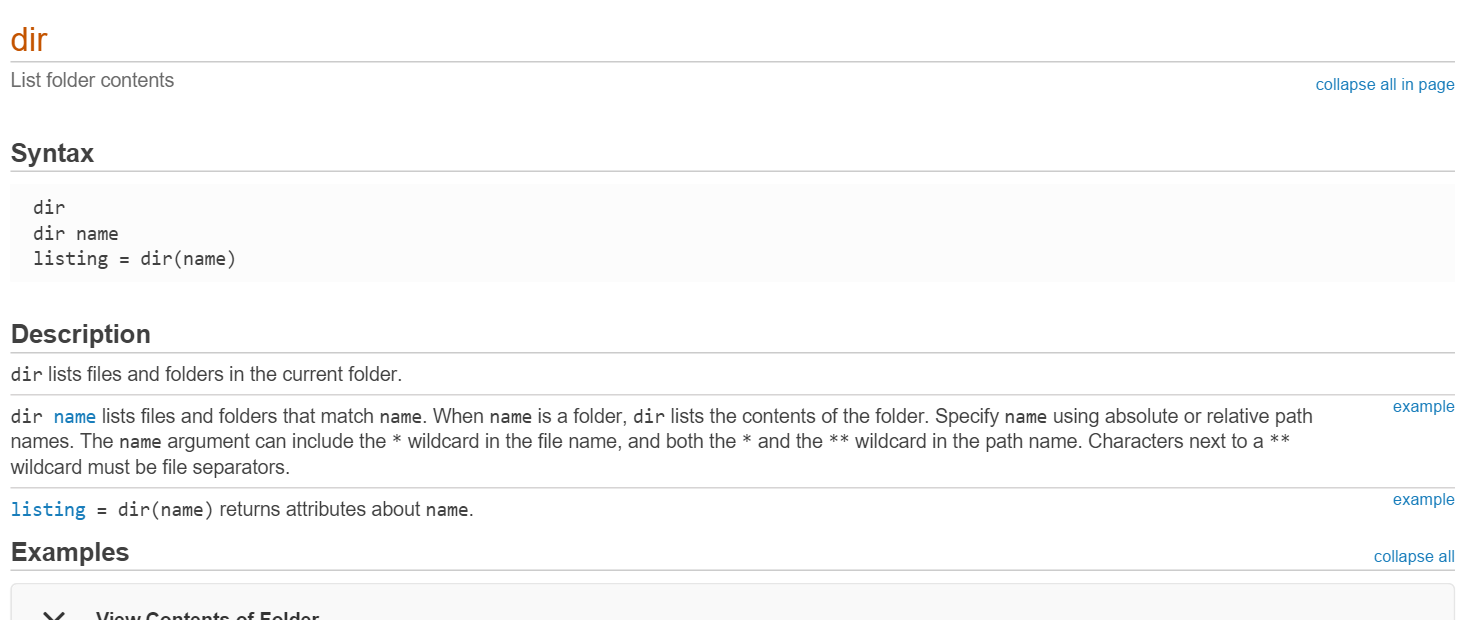

**看文档下部的相关函数**

我们拉到该文档的地步，可以看到dir相关的函数如cd、mkdir等等。还可以看到dir函数是在什么时候引入的，这里是R2006a前引入的。